# BP Network

neural network for 6-DoF pose tracking

clear
load('./NNdata(40mm).mat');
clear bpout_S

## Data process

% 
% input_train=[mag_train_random_noise(1:5:end,:)]';
% 
% output_train=[tr_train_random_noise(1:5:end,:)]';  % The training set was rearranged, and noise added.
% 
% % [inputn,inputps]=mapminmax(input_train);
% % [outputn,outputps]=mapminmax(output_train);
% % [outputP,outputpsP]=mapminmax(output_train(5:7,:));
% 

## Net configuration

% net=feedforwardnet([18,24,30,21,12],'trainscg');
% net.trainParam.epochs=1000000000;
% net.trainParam.lr=0.001;
% net.trainParam.goal=0.0001;
% net.trainParam.max_fail=15;
% % net.divideFcn='dividetrain';
% net.divideParam.trainRatio=0.8;
% net.divideParam.valRatio=0.2;

## Training

% % output=single([outputO;outputP]);
% % input=single(inputn);
% input_gpu=gpuArray(inputn);
% output_gpu=gpuArray(outputn);
% tic;
% net=train(net,input_gpu,output_gpu,'useGPU','yes')
% % y=net([outputO;outputP],'useParallel','yes','showResources','yes')
% toc

## Test

% Note that the training data was selected randomly from the training set. 
% Thus the parameters 'inputps' and 'ouotputps' would be different each
% time, which would make the results different.

output_test=tr_test(800:1950,:)';

input_test=mapminmax('apply',mag_test(800:1950,:)',inputps); % test data 


an=sim(net,input_test);  % network forwark prediction

bpout=mapminmax('reverse',an,outputps)';    
for i=1:6
    bpout_S(:,i)=smooth(bpout(:,i),49);
end
% BPoutputO=mapminmax('reverse',an(1:4,:),outputpsO);
% BPoutputP=mapminmax('reverse',an(5:7,:),outputpsP);
%BPoutput(:,5:7)=(mapminmax('reverse',an(4:6,:),outputpsP))';

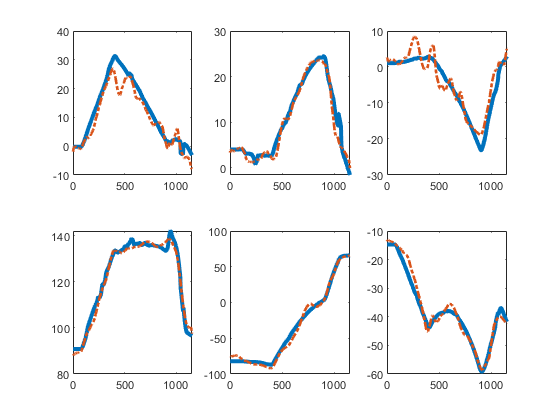

figure;
for i1=1:6
    subplot(2,3,i1);
    plot(output_test(i1,:)','DisplayName','output_test','LineWidth',3.0);
    hold on
    plot(bpout_S(:,i1),'-.','DisplayName','bpout_S','LineWidth',2.0);
end

## Validation


BPerrors=(bpout_S-output_test');
% for i=1:length(output_test(1,:))
%     reference_E(i,:)=quat2eul(output_test(:,i)')*180/pi;
%     bp_E(i,:)=quat2eul(bpout_S(i,:))*180/pi;
% end
% BPerrors_E=(bp_E-reference_E);
rmse=rms(BPerrors)

rmse =     3.5891    1.6163    2.9385    2.0915    4.9784    2.1903


maxe=max(abs(BPerrors))

maxe =    11.4271    6.0567    6.0424    5.1934   10.5190    5.8719


avere=mean(abs(BPerrors))

avere =     2.7242    1.1371    2.3585    1.6939    4.0653    1.7010


## figure

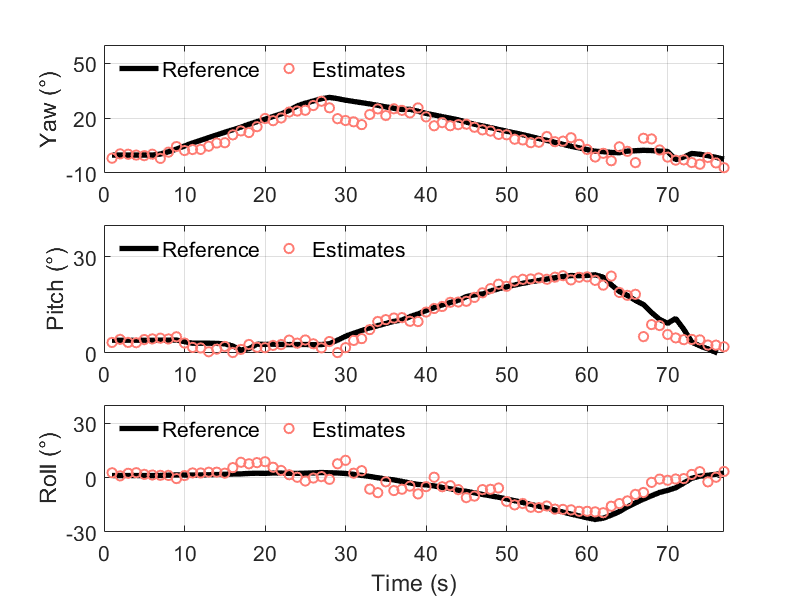

figure('Position',[100 100 800 600]);
hold off;
subplot(3,1,1);
plot(output_test(1,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,1),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([-10 60]);
yticks(-10:30:60);
ylabel('Yaw (°)');
% title('Reference and estimation euler orientation','FontSize',24);

subplot(3,1,2);
plot(output_test(2,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,2),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([0 40]);
yticks(0:30:40);
ylabel('Pitch (°)');

subplot(3,1,3);
plot(output_test(3,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,3),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([-30 40]);
yticks(-30:30:40);
xlabel('Time (s)');
ylabel('Roll (°)');

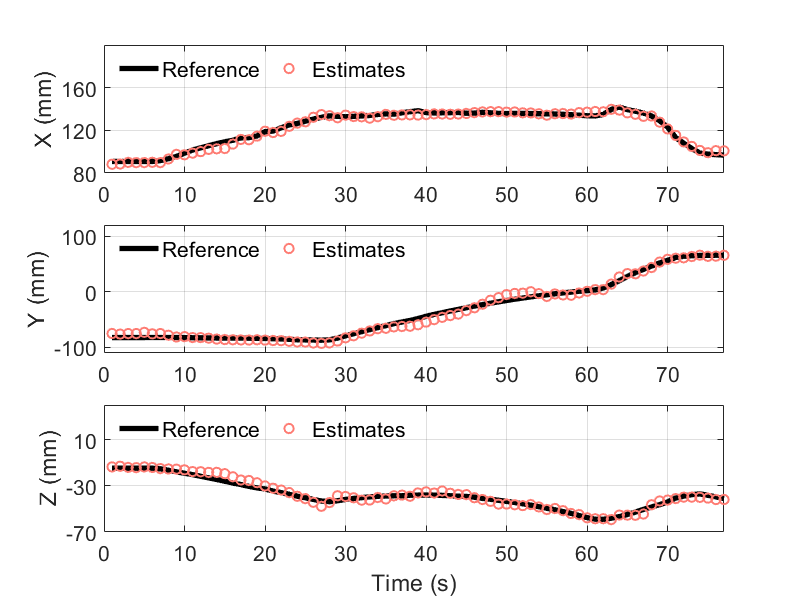


figure('Position',[100 100 800 600]);
hold off;
subplot(3,1,1);
plot(output_test(4,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,4),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([80 200]);
yticks(80:40:180);
ylabel('X (mm)');
% title('Reference and estimation position','FontSize',24,'FontWeight','bold');

subplot(3,1,2);
plot(output_test(5,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,5),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([-110 120]);
% yticks(-110:70:120);
ylabel('Y (mm)');

subplot(3,1,3);
plot(output_test(6,1:15:end)','-','LineWidth',4,'Color','black');
hold on;
plot(bpout(1:15:end,6),'o','MarkerEdgeColor','#FE7B72','MarkerSize',7,'LineWidth',1.5);
set(gca,'FontSize',16);
legend({'Reference','Estimates'},'FontSize',16,'Orientation','horizontal','Location',"northwest",'Box',"off");
grid on;
xlim([0 77]);
ylim([-70 40]);
yticks(-70:40:40);
xlabel('Time (s)');
ylabel('Z (mm)');

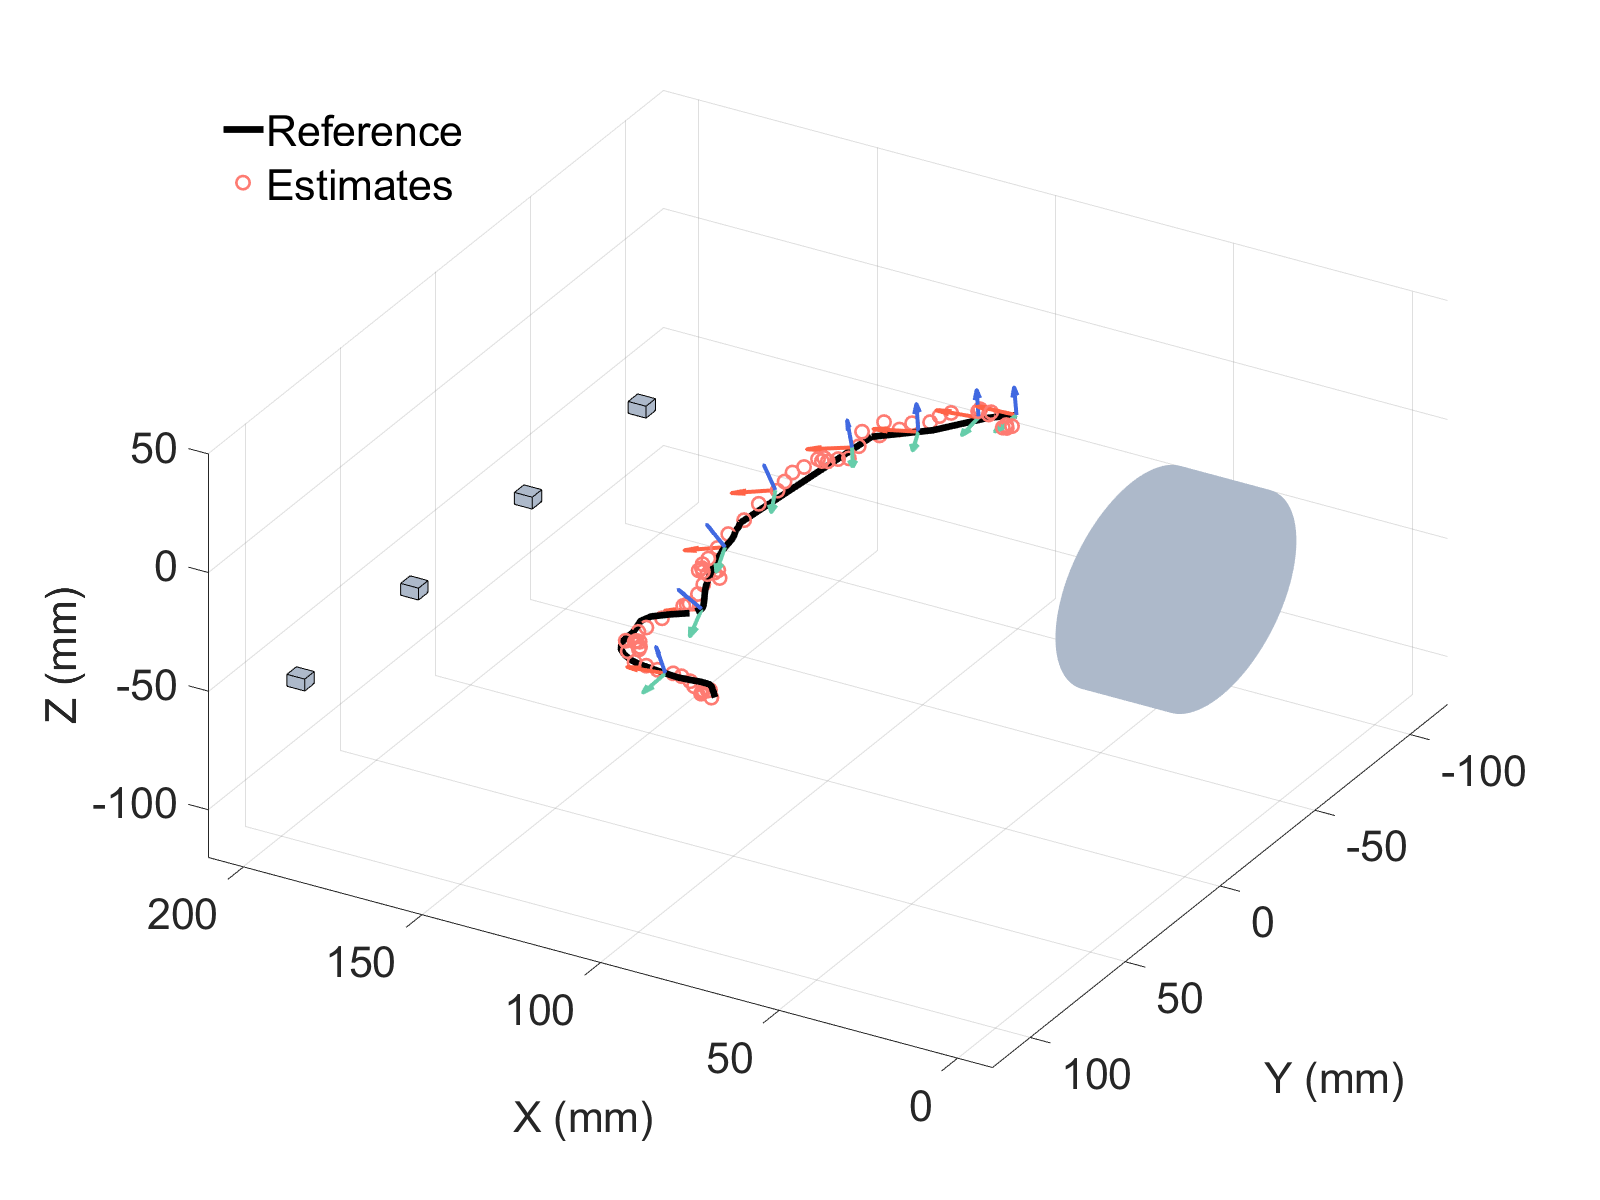

clear Rx Ry Rz
figure('Position',[100 100 1600 1200])
grid off
hold on;
plot3(tr_test(801:135:1206,4),tr_test(801:135:1206,5),tr_test(801:135:1206,6),'-','Color','black','LineWidth',5);
plot3(bpout(1:30:400,4),bpout(1:30:400,5),bpout(1:30:400,6),'o','MarkerEdgeColor','#FE7B72','MarkerSize',10,'LineWidth',2);
plot3(tr_test(1206:285:1491,4),tr_test(1206:285:1491,5),tr_test(1206:285:1491,6),'-','Color','black','LineWidth',5);
plot3(bpout(400:19:685,4),bpout(400:19:685,5),bpout(400:19:685,6),'o','MarkerEdgeColor','#FE7B72','MarkerSize',10,'LineWidth',2);
plot3(tr_test(1490:10:1715,4),tr_test(1490:10:1715,5),tr_test(1490:10:1715,6),'-','Color','black','LineWidth',5);
plot3(bpout(685:15:910,4),bpout(685:15:910,5),bpout(685:15:910,6),'o','MarkerEdgeColor','#FE7B72','MarkerSize',10,'LineWidth',2);
plot3(tr_test(1716:10:1950,4),tr_test(1716:10:1950,5),tr_test(1716:10:1950,6),'-','Color','black','LineWidth',5);
plot3(bpout(910:10:end,4),bpout(910:10:end,5),bpout(910:10:end,6),'o','MarkerEdgeColor','#FE7B72','MarkerSize',10,'LineWidth',2);
set(gca,'FontSize',32);
% [XS1,YS1,ZS1]=ellipsoid(200,-90,-60,2,2,2);
% [XS2,YS2,ZS2]=ellipsoid(200,-30,-60,2,2,2);
% [XS3,YS3,ZS3]=ellipsoid(200,30,-60,2,2,2);
% [XS4,YS4,ZS4]=ellipsoid(200,90,-60,2,2,2);
% quiver3(200,-90,-60,1,0,0,10,'Color','#FF6347','LineWidth',3);
% quiver3(200,-90,-60,0,1,0,10,'Color','#66CDAA','LineWidth',3);
% quiver3(200,-90,-60,0,0,1,10,'Color','#4169E1','LineWidth',3);
% quiver3(200,-30,-60,1,0,0,10,'Color','#FF6347','LineWidth',3);
% quiver3(200,-30,-60,0,1,0,10,'Color','#66CDAA','LineWidth',3);
% quiver3(200,-30,-60,0,0,1,10,'Color','#4169E1','LineWidth',3);
% quiver3(200,30,-60,1,0,0,10,'Color','#FF6347','LineWidth',3);
% quiver3(200,30,-60,0,1,0,10,'Color','#66CDAA','LineWidth',3);
% quiver3(200,30,-60,0,0,1,10,'Color','#4169E1','LineWidth',3);
% quiver3(200,90,-60,1,0,0,10,'Color','#FF6347','LineWidth',3);
% quiver3(200,90,-60,0,1,0,10,'Color','#66CDAA','LineWidth',3);
% quiver3(200,90,-60,0,0,1,10,'Color','#4169E1','LineWidth',3);
% surf(XS1,YS1,ZS1,'FaceColor','#778899');
% surf(XS2,YS2,ZS2,'FaceColor','#778899');
% surf(XS3,YS3,ZS3,'FaceColor','#778899');
% surf(XS4,YS4,ZS4,'FaceColor','#778899');

% 定义方块的参数
cubeSize = 5; % 方块的三维尺寸
cubeColor = '#ADB9CA'; % 方块的颜色

% 定义方块的位置
cubePositions = [200 -90 -60; 200 -30 -60; 200 30 -60; 200 90 -60];

% 绘制四个方块
hold on;
for i = 1:size(cubePositions, 1)
    % 计算方块的顶点坐标
    x = cubePositions(i, 1);
    y = cubePositions(i, 2);
    z = cubePositions(i, 3);
    
    % 绘制一个方块
    [X, Y, Z] = meshgrid([x-cubeSize/2, x+cubeSize/2], [y-cubeSize/2, y+cubeSize/2], [z-cubeSize/2, z+cubeSize/2]);
    cube = zeros(8,3);
    cube(:,1) = X(:);
    cube(:,2) = Y(:);
    cube(:,3) = Z(:);
    
    % 定义方块的面
    faces = [1 2 6 5; 2 4 8 6; 4 3 7 8; 3 1 5 7; 5 6 8 7; 1 2 4 3];
    
    % 绘制方块
    patch('Vertices', cube, 'Faces', faces, 'FaceColor', cubeColor, 'EdgeColor', 'black');
end

% 定义圆柱体的参数
diameter = 80; % 圆柱体的直径
radius = diameter / 2; % 圆柱体的半径
height = 30; % 圆柱体的高度
resolution = 100; % 分辨率，值越大，边缘越光滑

% 创建圆柱体的网格
theta = linspace(0, 2*pi, resolution);
z = linspace(-height/2, height/2, resolution);
[Theta, Z] = meshgrid(theta, z);

% 计算圆柱体的x、y和z坐标
X = Z;
Y = radius * cos(Theta);
Z = radius * sin(Theta);

% 绘制圆柱体
hold on;
cylinder = surf(X, Y, Z);

% 设置颜色和边缘属性
cylinder.FaceColor = '#ADB9CA';
cylinder.EdgeColor = 'none';

% 创建圆的网格
r = linspace(-radius, radius, resolution);
[R, Theta] = meshgrid(r, theta);

% 计算圆的x、y和z坐标
X_circle1 = R*0-height/2; % 朝向X轴，所以X坐标为-height/2
Y_circle1 = R .* cos(Theta);
Z_circle1 = R .* sin(Theta);

% 绘制一个圆
circle1 = surf(X_circle1, Y_circle1, Z_circle1);

% 设置颜色和边缘属性
circle1.FaceColor = '#ADB9CA';
circle1.EdgeColor = 'black';

% 计算另一个圆的x、y和z坐标
X_circle2 = R*0+height/2; % 朝向X轴，所以X坐标为+height/2

% 绘制另一个圆
circle2 = surf(X_circle2, Y_circle1, Z_circle1);

% 设置颜色和边缘属性
circle2.FaceColor = '#ADB9CA';
circle2.EdgeColor = 'none';

xlim([-10 210]);
ylim([-120 120]);
zlim([-120 50]);
view([-149.9 46.2]);
% [x, y, z] = ellipsoid(0,0,0,10,8,4);
% quiver3(0,0,0,1,0,0,25,'Color','#FF6347','LineWidth',3);
% quiver3(0,0,0,0,1,0,25,'Color','#66CDAA','LineWidth',3);
% quiver3(0,0,0,0,0,1,25,'Color','#4169E1','LineWidth',3);
% surf(x, y, z,'FaceColor','#C0C0C0');
grid on;
% text(200,-100,-60,'Sensor1');
% text(200,-40,-60,'Sensor2');
% text(200,20,-60,'Sensor3');
% text(200,80,-60,'Sensor4');
% text(10,-30,10,'Electromagnet');
% plot3(tr_1S(:,4),tr_1S(:,5),tr_1S(:,6),'-.','Color','#FF6347','LineWidth',3.0);
for i1=1:8
    j1=((i1-1)*150)+801;
    Rx(i1,:)=eul2rotm(tr_test(j1,1:3)*pi/180)*[1;0;0];
    Ry(i1,:)=eul2rotm(tr_test(j1,1:3)*pi/180)*[0;1;0];
    Rz(i1,:)=eul2rotm(tr_test(j1,1:3)*pi/180)*[0;0;1];
end
quiver3(tr_test(801:150:1950,4),tr_test(801:150:1950,5),tr_test(801:150:1950,6),Rx(:,1),Rx(:,2),Rx(:,3),0.2,'Color','#FF6347','LineWidth',3);
quiver3(tr_test(801:150:1950,4),tr_test(801:150:1950,5),tr_test(801:150:1950,6),Ry(:,1),Ry(:,2),Ry(:,3),0.2,'Color','#66CDAA','LineWidth',3);
quiver3(tr_test(801:150:1950,4),tr_test(801:150:1950,5),tr_test(801:150:1950,6),Rz(:,1),Rz(:,2),Rz(:,3),0.2,'Color','#4169E1','LineWidth',3);
% plot3(tr_2S(:,4),tr_2S(:,5),tr_2S(:,6),'-.','Color','#66CDAA','LineWidth',3.0);
% plot3(tr_3S(:,4),tr_3S(:,5),tr_3S(:,6),'-.','Color','#4169E1','LineWidth',3.0);
xlabel('X (mm)','FontSize',32);
ylabel('Y (mm)','FontSize',32);
zlabel('Z (mm)','FontSize',32);
% title('Translation trajectory and orientation in Cartesian space','FontSize',32);
legend({'Reference','Estimates'},'FontSize',32,'Orientation','vertical','Location',"northwest",'Box',"off");

% legend({'Tx','Ty','Tz'},'FontSize',12);
